**E3DSB Opgaver 4**

**Opgave 4.1**

clear all; clc; close all;

Lav i Matlab et signal x(n), med N=200 tilfældige værdier.

N = 200;
x = randn(1,N);

Filterkoefficienter:

h_LP = ones([1 8])/8;
h_HP = [1 -1 1 -1]; %det kunne give mening at dele med 4 her for at få middel

a) Filtrer x(n) med hver af de to filtre

y_LP = filter(h_LP, 1, x);
y_HP = filter(h_HP, 1, x);

b) Plot input og output i samme figur

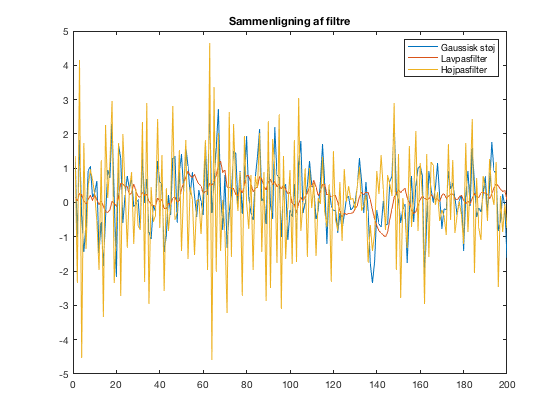

plot(x);
hold on;
plot(y_LP);
plot(y_HP);
title('Sammenligning af filtre');
legend('Gaussisk støj','Lavpasfilter','Højpasfilter');

Figuren viser effekt af filtrering på den gaussiske støj med hhv. lavpas- og højpasfilter:

- Lavpasfilteret er et 8-tap midlingsfilter (glidende gennemsnit, MA).

- Højpasfilteret er ikke "midlet", så indeholder derfor en "gain"-faktor på 4.

c) Blokdiagrammer for de to filtre:

Lavpasfilter:

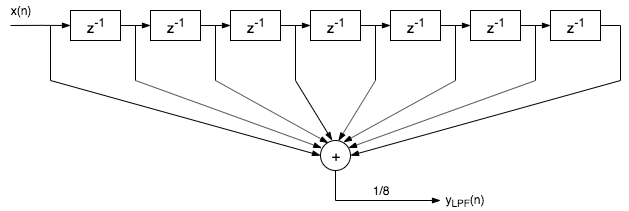

Højpasfilter: